# Example Coding Exercise

## Task 1: K-Nearest Neighbors

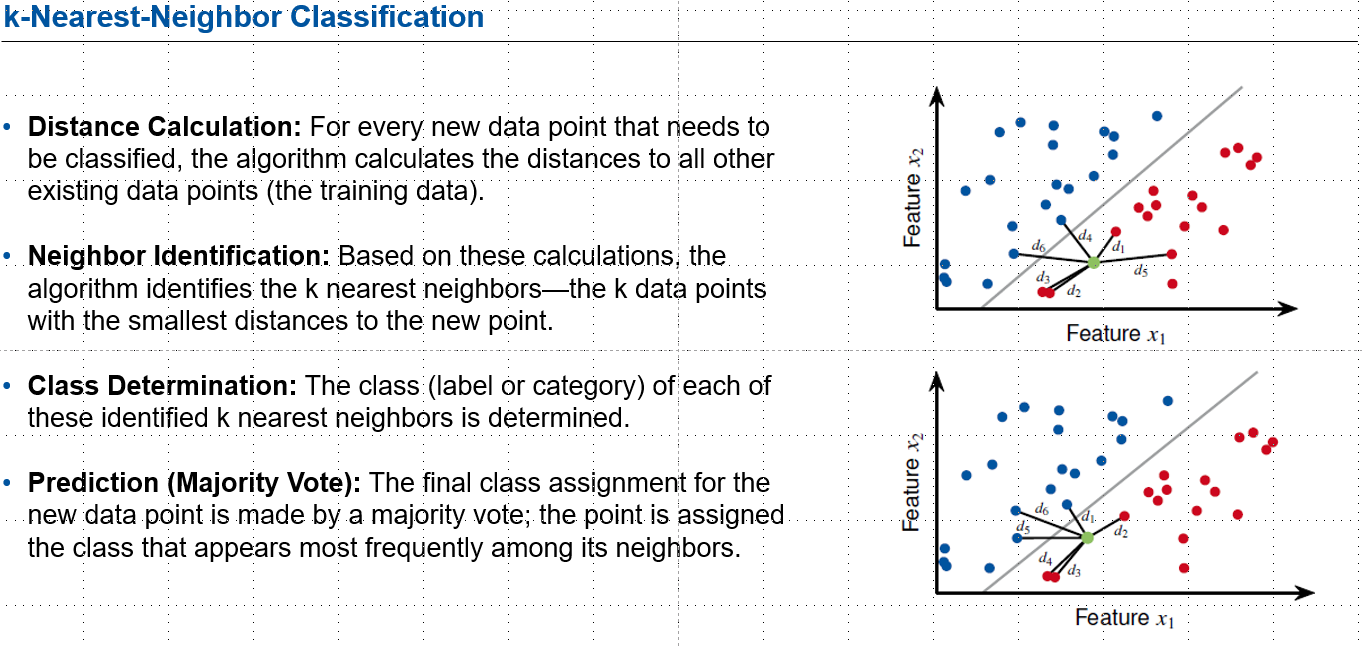

### a) Implementation of the algorithm

Please implement the k-nearest neighbors algorithm and test it on the data in "data_task1.mat". Please fill the function body of "k_nearestNeighbors" given at the end of the subtask. To check the results, please uncomment the corresponding line (line 20) inside the code block below.

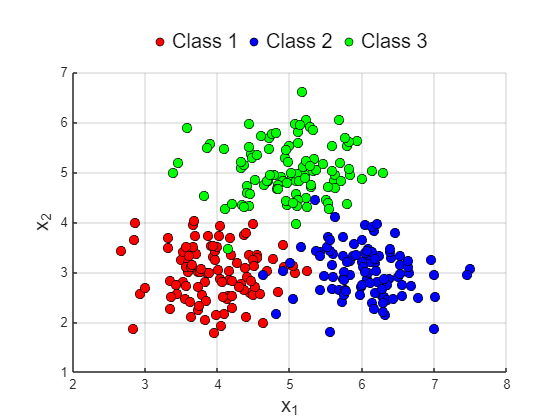

% - start solution 0_1_a_1

clear; clc;
addpath("documents\"); 

%% Load the data
load("data_task1.mat"); 

% Define colors for each class
colors = {'red', 'blue', 'green'};

nTestPoints = size(xTest, 1);            % number of test points
nClasses    = length(unique(Y_train));   % number of different classes
k           = 3;                         % number of nearest neighbors 

% Initialize predictions and class-specific storage
yPred = zeros(nTestPoints, 1);

% Classify each test point
for i = 1:nTestPoints
    % yPred(i) = k_nearestNeighbors(X_train, Y_train, xTest(i, :), k);
end

% ------------------- Visualization ---------------------------------

%% Visualize the results
figure('Name','0_1_a_1'); 
hold on;
% Plot training data
for i = 1:nClasses
    scatter(X_train(Y_train == i,1), X_train(Y_train == i, 2), ...
            50, 'filled', 'MarkerEdgeColor','black', 'MarkerFaceColor', colors{i});
end
% Plot test data colored by predicted class
for i = 1:nClasses
    scatter(xTest(yPred == i,1),xTest(yPred == i,2), 150, ...
            'MarkerFaceColor', colors{i}, 'Marker', 'square', ...
            'MarkerEdgeColor', 'black');
end
grid on; 
hold off;
xlabel('x_1', 'FontSize', 15); 
ylabel('x_2', 'FontSize', 15); 
legendEntries = strcat("Class ", string(1:nClasses));
legend(legendEntries, 'Location', 'northoutside', ...
       'FontSize', 15, 'Orientation', 'horizontal', 'Box', 'off');

% - end solution 0_1_a_1

The function body for the k-nearest-neighbors algorithm is given below. Please fill the empty function body.

% - start solution 0_1_a_2

function [yPred] = k_nearestNeighbors(X_train, Y_train, xTest, k)
    % function for implementing k-nearest neighbors

    % Inputs: 
    %   X_train:       array containing the x and y coordinates for each
    %                  point (nPoints x nDimensions)
    %   Y_train:       array containing the labels
    %   xTest:         point that we want to classify (nPoints x nDimensions)
    %   k:             number of nearest neighbors

    % Outputs: 
    %   yPred:         class for xTest; should take values from 1 to 3

    % number of different classes: 
    nClasses = length(unique(Y_train)); 

    % number of training-data points: 
    nPoints = size(X_train,1);

    % add your code here: 



    % yPred = ...; 

end

% - end solution 0_1_a_2

### **b) Question about the k-nearest-neighbor method: **

Why is selecting an even value for the number of nearest neighbors "k" for classification a bad idea? 

%{
% - start freeText 0_1_b_1

...

% - end freeText 0_1_b_1
%}

## Task 2: K-means Clustering

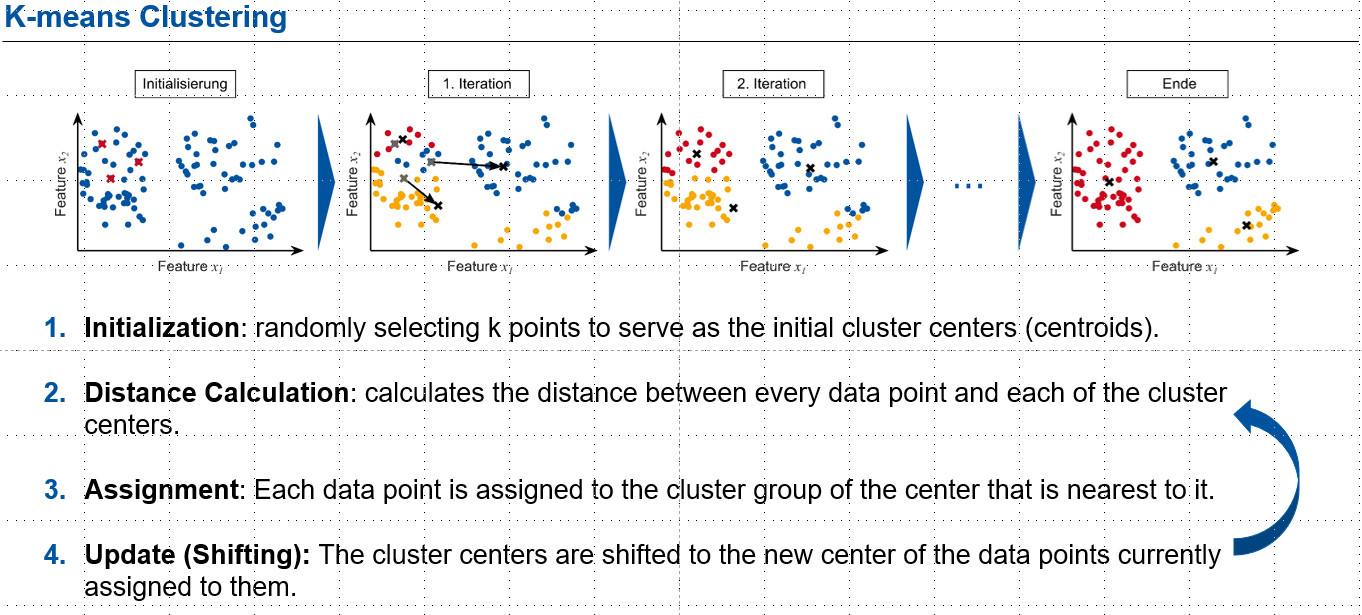

The following task is about implementing the k-means clustering algorithm.

**2a) Please implement the k-nearest neighbors algorithm. The function body is already given at the end of this task.**

**Steps:**

- **Initialize: ** Select data points randomly and assign them to the new cluster centrums.

- **Assignment:**  Assign each data point to the nearest centrum.

- **Update:** Update the cluster positions by using the mean over the assigned data points.

- **Repeat** for m_iter times

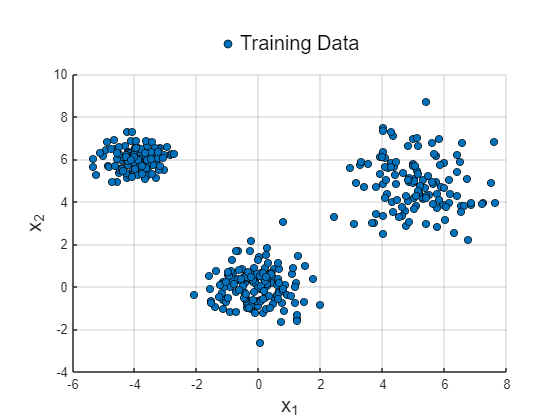

clear; clc;
addpath("documents\"); 

% load the training data: 
load("data_task2.mat");

% Visualize the training data: 
scatter(Xtraining(:, 1), Xtraining(:,2), 30, ...
      'filled', 'o', 'MarkerEdgeColor','black'); 
xlabel('x_1', 'FontSize',15); 
ylabel('x_2', 'FontSize',15); 
grid on; 
legend('Training Data', 'Location','northoutside', ...

    'FontSize',15, 'Orientation', 'horizontal', 'box', 'off'); 

% - start solution 0_2_a_1

% Parameters: 
mIter     = 100;    % number of iterations
nClusters = 3;      % number of clusters

% use your algorithm:
[centrumPos, clusteredData] = k_meansClustering(Xtraining, mIter, nClusters); 

% Plot the results:  
figure('Name', '0_2_a_1');
for i = 1 : nClusters
    scatter(clusteredData{i}(:,1), clusteredData{i}(:,2), 30, ...
            'filled', 'MarkerEdgeColor','black'); hold on; 
end
hold off; 
legend(num2str((1:1:nClusters)'), 'Location','northoutside', ...
    'FontSize',15, 'Orientation', 'horizontal', 'box', 'off'); 
grid on; 
xlabel('x_1', 'FontSize',15); 
ylabel('x_2', 'FontSize',15); 
% - end solution 0_2_a_1

Here, the algorithm for the k-means clustering is to be implemented.

Please, fill the function body below:

% - start solution 0_2_a_2

function [centrumPos, clusteredData] = k_meansClustering(Xtraining, mIter, nClusters)
    
    % function for implementing the k-means clustering 
    % algorithm

    % ----------------------- Inputs ------------------------------------ 
    % mIter:          number of iterations
    % Xtrain:         training data (nPoints x nDimensions)
    % nClusters:      number of clusters

    % ---------------------- Outputs ------------------------------------
    % centrumPos:     positions of cluster centrums
    % clusteredData:  data that is clustered intro nClusters groups (cell
    %                 array)

    % assign initial clusters randomly: 
    randomIdx     = RandStream('mt19937ar','Seed', 1);
    index         = randomIdx.randperm(size(Xtraining,1), nClusters);
    centrumPos     = Xtraining(index,:);
    nPoints        = size(Xtraining, 1); 

    % the clustered data (can be filled by clusteredData{i} = ...)
    clusteredData = cell(nClusters, 1);

    for n = 1 : mIter
        % add your code here: 
        
    
    end

end


% - end solution 0_2_a_2

**2b) What are possible approaches, when the algorithm converges to a suboptimal result?**

**Please answer the question inside the code block.**

%{
% - start freeText 0_2_b_1

...

% - end freeText 0_2_b_1
%}